%% 1D acoustic solver with two separable sources
clear
close all
clc

% Grid and medium
grid_cmp = GridSpace1D( ...
    Grid1DUnifPrimal([0,1],401));

grid_out = GridSpace1D( ...
    Grid1DUnifPrimal([0,1],201));

medium = AcousticMedium1D.constant( ...
    KappaValue=1, ...
    BetaValue=1);

% Time discretization
% Select dt below the fourth-order CFL limit of 6/7.
[~,~,~,cMax] = sampleMedium1D(grid_cmp,medium);
CFL = 0.8*(6/7);
dt = CFL*grid_cmp.h/cMax;
times_cmp = 0:dt:0.8;
times_out = linspace(0,times_cmp(end),81);

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% First pressure source
% Spatially centered near x = 0.30 and temporally centered near t = 0.10.
source1 = AcousticSource1D( ...
    @(x) exp(-((x-0.30)/0.035).^2), ...
    @(t) exp(-((t-0.10)/0.025).^2));

% Second pressure source
% The negative amplitude gives the second source the opposite polarity.
source2 = AcousticSource1D( ...
    @(x) -0.8*exp(-((x-0.70)/0.045).^2), ...
    @(t) exp(-((t-0.20)/0.035).^2));

% Combine the sources

% The resulting pressure forcing is
%   f_p(x,t) = g_1(x)w_1(t) + g_2(x)w_2(t).
source = AcousticSource1D.combine({source1,source2});

disp("Number of pressure-source terms: " + ...
    source.numberOfPressureTerms)

Number of pressure-source terms: 2


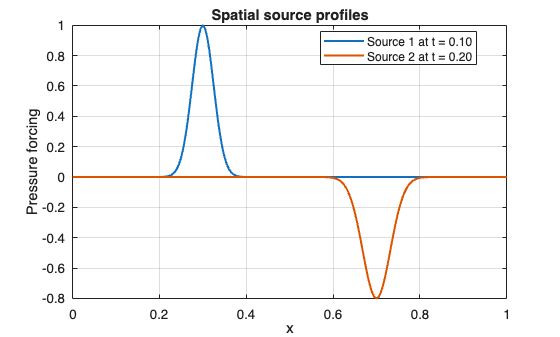


% Plot the source profiles
x = grid_out.x.pts;

figure
plot(x,source1.evaluatePressure(x,0.10), ...
    LineWidth=1.5)
hold on
plot(x,source2.evaluatePressure(x,0.20), ...
    LineWidth=1.5)

hold off
grid on

xlabel("x")
ylabel("Pressure forcing")
title("Spatial source profiles")

legend( ...
    "Source 1 at t = 0.10", ...
    "Source 2 at t = 0.20", ...
    Location="best")


% Initialize the solver
solver = AcousticSolver1DStaggered( ...
    grid_cmp, ...
    times_cmp, ...
    grid_out, ...
    times_out, ...
    medium, ...
    SpatialOrder=4);

% Run the solver
[P,V] = solver.solve( ...
    p0, ...
    v0, ...
    Source=source);

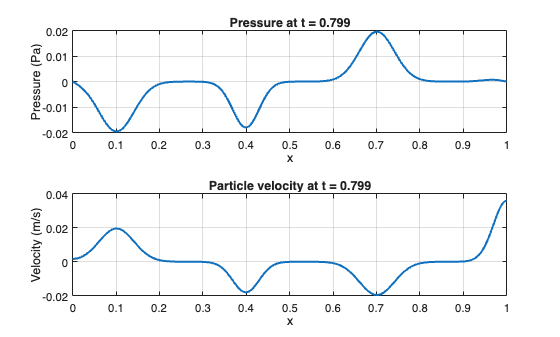

% Plot the final solution
figure
tiledlayout(2,1)

nexttile
plot(grid_out.x.pts,P.values(:,end), ...
    LineWidth=1.5)

grid on
xlabel("x")
ylabel("Pressure (Pa)")
title(sprintf("Pressure at t = %.3f",P.times(end)))

nexttile
plot(grid_out.x.pts,V.values(:,end), ...
    LineWidth=1.5)

grid on
xlabel("x")
ylabel("Velocity (m/s)")
title(sprintf( ...
    "Particle velocity at t = %.3f",V.times(end)))

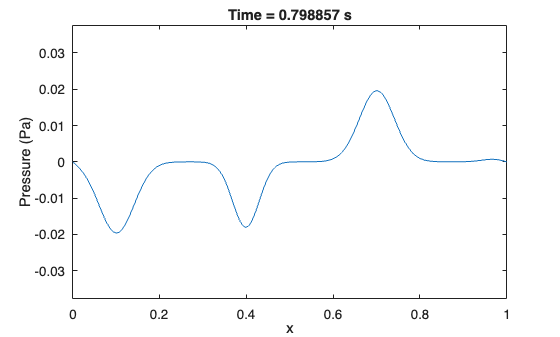

% Animate the solution
P.animate(FramePause=0.03);


% Run this separately if you also want the velocity animation:
% V.animate(FramePause=0.03);